# CIFI V. Problema: Digitt. Materia: Metodos de Inteligencia Artificial

## Cargamos datos

load Digitt.mat
data

data =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -0.5972   -0.1960    0.9629    0.4280    0.3834   -0.5393    0.6063   -0.5972    0.6063   -0.6774   -0.3298   -0.5749   -0.1069   -0.8424   -0.7101   -0.8201   -0.3966   -0.3298   -0.1515   -0.5081   -0.8201   -0.1515    1.0074   -0.5883    0.2943    0.1605    0.0714   -0.3743   -0.6864   -0.6864   -0.3743    2.5230   -0.4412   -0.5081    0.5171   -0.5081   -0.0178   -0.5303    0.2943    0.6954   -0.5972   -0.4412    0.2943    0.1516   -0.1069    2.5230    4.3059   -0.1515   -0.1960  

## Los datos y su estructura (datos ya estandarizados)

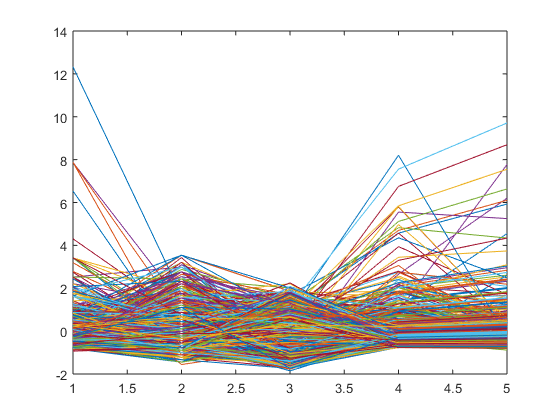

% income age score total_debt amount_to_be_lend
plot(X1')

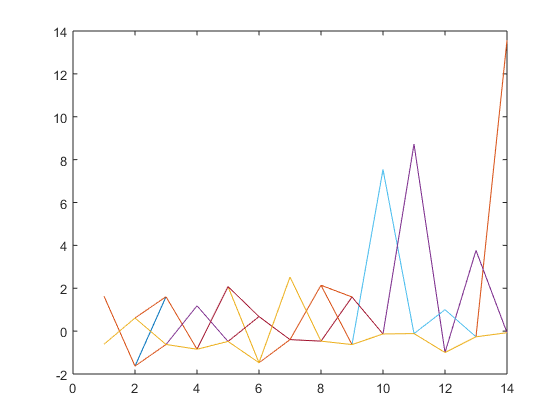

% gender housing_type level_of_studies marital_status
plot(X2')

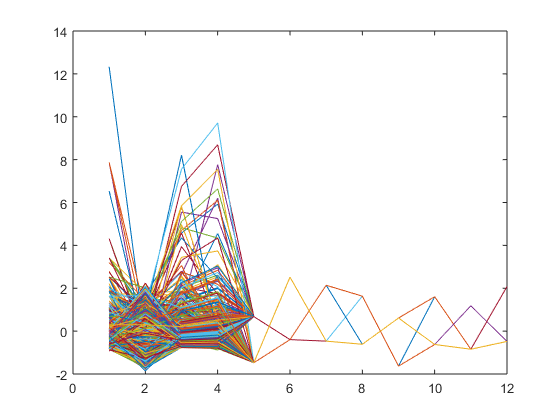

% income score total_debt amount_to_be_lend level_of_studies gender housing_type
plot(X3')

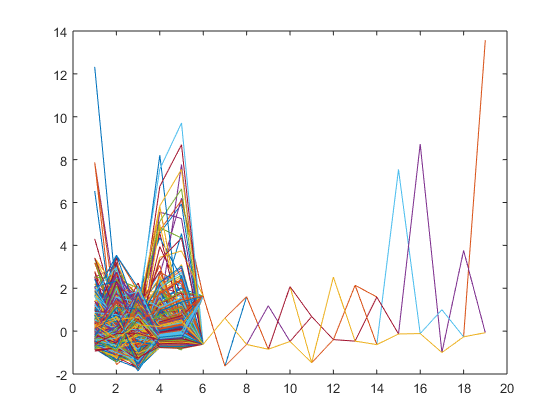

% income age score total_debt amount_to_be_lend gender housing_type level_of_studies marital_status
plot(X4')

## Importancia de los pesos del perceptron

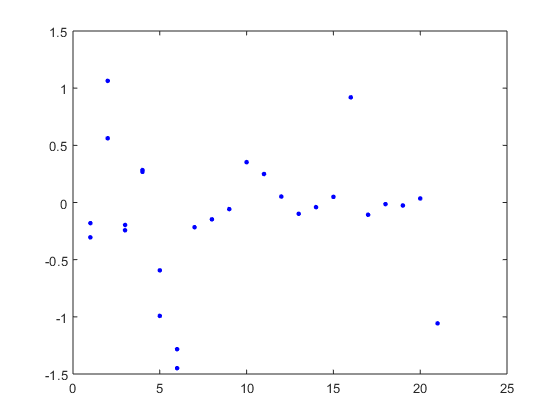

% income age score total_debt amount_to_be_lend
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',1,k));
    hold on 
end
hold off

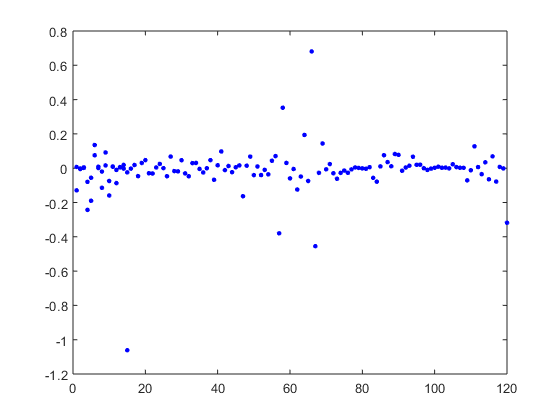


% gender housing_type level_of_studies marital_status
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',2,k));
    hold on 
end
hold off

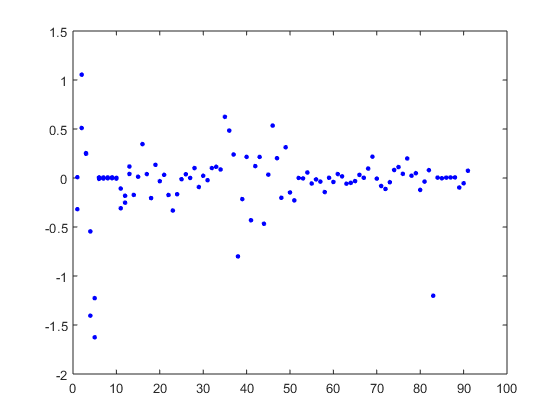


% income score total_debt amount_to_be_lend level_of_studies gender housing_type
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',3,k));
    hold on 
end
hold off

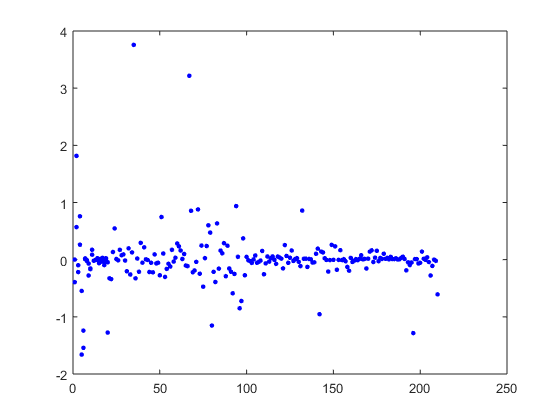


% income age score total_debt amount_to_be_lend gender housing_type level_of_studies marital_status
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',4,k));
    hold on 
end
hold off

## Desempeño de los modelos

Desempenio

Desempenio = struct with fields:
    m1g1: [0.6882 0.7394 0.6587]
    m2g1: [0.5771 0.3808 0.6000]
    m3g1: [0.6926 0.7283 0.6673]
    m4g1: [0.6936 0.7372 0.6660]
    m1g2: [0.7033 0.7728 0.6673]
    m2g2: [0.6052 0.5367 0.6040]
    m3g2: [0.7141 0.7528 0.6870]
    m4g2: [0.7627 0.7884 0.7390]


## Estimados (Predicciones)

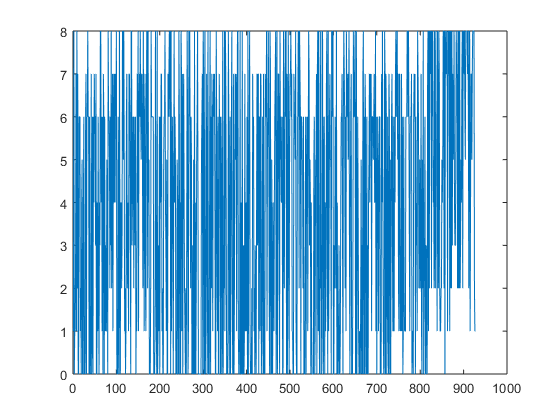

YgGlobal = zeros(size(Y));
for k=1:2
    for i=1:4
        eval(sprintf('YgGlobal = YgGlobal + Yg.m%dg%d;',i,k));
    end
end
plot(YgGlobal)

## Porcentaje de aciertos en 1's y 0's para predicciones comunes entre los modelos

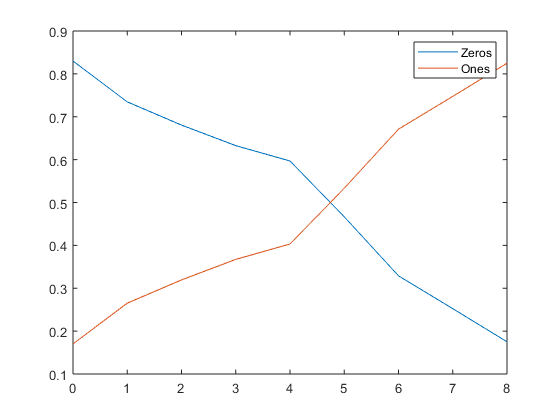

zeros_ = zeros(9,1);
ones_ = zeros(9,1);
for i=1:9
    tmp00 = sum(~(YgG(YgG==i-1)==i-1)-Y(YgG==i-1));
    tmp01 = sum((YgG(YgG==i-1)==i-1));
    zeros_(i) = 1 + tmp00/tmp01; % 1 - error en los predichos 
    
    tmp10 = sum((YgG(YgG==i-1)==i-1)-Y(YgG==i-1));
    tmp11 = sum(YgG(YgG==i-1)==i-1);
    ones_(i) = 1- tmp10/tmp11; % 1 - error en los predichos 
end
plot([0:8],zeros_)
hold on
plot([0:8],ones_)
hold off
legend('Zeros','Ones')

## Porcentaje de aciertos acumulativos en 1's y 0's para predicciones comunes entre los modelos

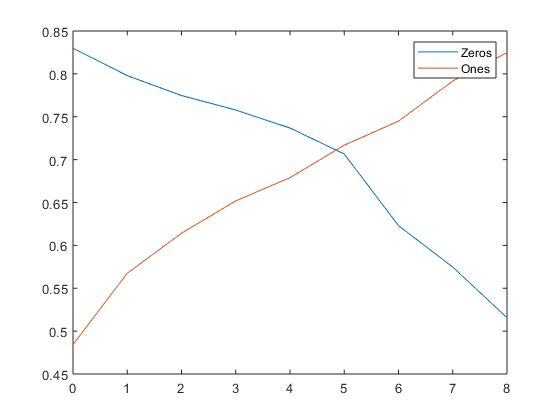

zeros_ = zeros(9,1);
ones_ = zeros(9,1);
for i=1:9
    tmp00 = sum(~(YgG(YgG<i)<i)-Y(YgG<i));
    tmp01 = sum((YgG(YgG<i)<i));
    zeros_(i) = 1 + tmp00/tmp01; % 1 - error en los predichos 
    
    tmp10 = sum((YgG(YgG>=i-1)>=i-1)-Y(YgG>=i-1));
    tmp11 = sum(YgG(YgG>=i-1)>=i-1);
    ones_(i) = 1- tmp10/tmp11; % 1 - error en los predichos 
end
plot([0:8],zeros_)
hold on
plot([0:8],ones_)
hold off
legend('Zeros','Ones')